# Connect to a ROS Network

A ROS network consists of a single *ROS master* and multiple *ROS nodes*. 

The ROS master facilitates the communication in the ROS network by keeping track of all active ROS entities. 

Every node needs to register with the ROS master to be able to communicate with the rest of the network. MATLAB® can start the ROS master, or the master can be launched outside of MATLAB (for example, on a different computer).

When you work with ROS, you typically follow these steps:

- *Connect to a ROS network*. To connect to a ROS network, you can create the ROS master in MATLAB or connect to an existing ROS master. In both cases, MATLAB will also create and register its own ROS node (called the MATLAB *global node*) with the master. The [`rosinit`](docid:ros_ref.bupf5_j_1) function manages this process.

- *Exchange data*. Once connected, MATLAB exchanges data with other ROS nodes through publishers, subscribers, and services. 

- *Disconnect from the ROS network*. Call the [`rosshutdown`](docid:ros_ref.bupf5_j_8) function to disconnect MATLAB from the ROS network. 

This example shows you how to:

- Create a ROS master in MATLAB

- Connect to an external ROS master

Prerequisites: [Get Started with ROS](docid:ros_ug.mw_cb3fdf75-613d-45b1-90e1-aad102b9a24a)

## Create a ROS Master in MATLAB

- To create the ROS master in MATLAB, call [`rosinit`](docid:ros_ref.bupf5_j_1) without any arguments. This function also creates the global node, which MATLAB uses to communicate with other nodes in the ROS network.

rosinit

Launching ROS Core...
..Done in 2.7232 seconds.
Initializing ROS master on http://172.30.135.126:50061.
Initializing global node /matlab_global_node_67598 with NodeURI http://bat6326win64:58586/ and MasterURI http://localhost:50061.


ROS nodes that are external to MATLAB can now join the ROS network. They can connect to the ROS master in MATLAB by using the hostname or IP address of the MATLAB host computer.

You can shut down the ROS master and the global node by calling [`rosshutdown`](docid:ros_ref.bupf5_j_8).

rosshutdown

Shutting down global node /matlab_global_node_67598 with NodeURI http://bat6326win64:58586/ and MasterURI http://localhost:50061.
Shutting down ROS master on http://172.30.135.126:50061.


## Connect to an External ROS Master

You can also use the [`rosinit`](docid:ros_ref.bupf5_j_1) command to connect to an external ROS master (for example running on a robot or a virtual machine). You can specify the address of the master in two ways: by an IP address or by hostname of the computer that runs the master.

After each call to `rosinit`, you have to call [`rosshutdown`](docid:ros_ref.bupf5_j_8) before calling `rosinit` with a different syntax. For brevity, these calls to `rosshutdown` are omitted in these examples.

`'master_host'` is an example host name and '`192.168.1.1'` is an example IP address of the external ROS master. Adjust these addresses depending on where the external master resides in your network. These commands will fail if no master is found at the specified addresses.

Both calls to [`rosinit`](docid:ros_ref.bupf5_j_1) assume that the master accepts network connections on port 11311, which is the standard ROS master port. If the master is running on a different port, you can specify it as a second argument. To connect to a ROS master running on host name `master_host` and port 12000, use the following command:

If you know the entire Uniform Resource Identifier (URI) of the master, you can create the global node and connect to this master using this syntax:

## Node Host Specification

In some cases, your computer may be connected to multiple networks and have multiple IP addresses. This illustration shows an example.

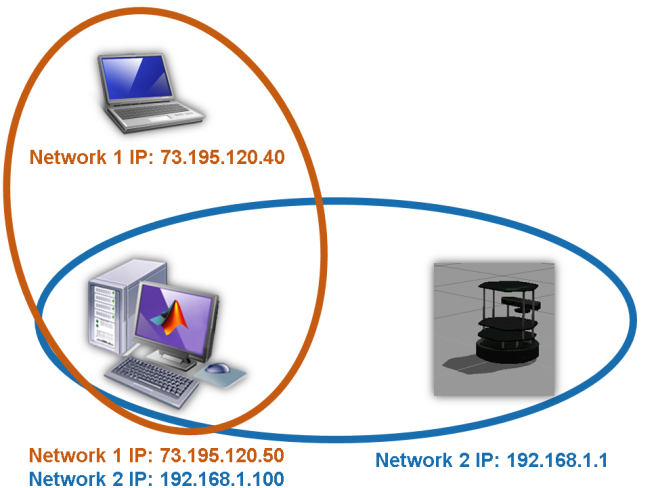

The computer on the bottom left runs MATLAB and is connected to two different networks. In one subnet, its IP address is `73.195.120.50,` and in the other, its IP is `192.168.1.100`. This computer wants to connect to the ROS master on the TurtleBot® computer at IP address `192.168.1.1`. As part of the registration with the master, the MATLAB global node has to specify the IP address or host name where other ROS nodes can reach it. All the nodes on the TurtleBot will use this address to send data to the global node in MATLAB.

When [`rosinit`](docid:ros_ref.bupf5_j_1) is invoked with the master's IP address, it tries to detect the network interface used to contact the master and use that as the IP address for the global node. If this automatic detection fails, you can explicitly specify the IP address or host name by using the `NodeHost` name-value pair in the `rosinit` call. The `NodeHost` name-value pair can be used with any of the other syntaxes already shown. 

These commands advertise your computer's IP address to the ROS network as `192.168.1.100`.

Once a node is registered in the ROS network, you can see the address that it advertises by using the command [`rosnode`](docid:ros_ref.bupf5_j_4)` info ``<nodename>`. You can see the names of all registered nodes by calling `rosnode list`.

## ROS Environment Variables

In advanced use cases, you might want to specify the address of a ROS master and your advertised node address through standard ROS environment variables. The syntaxes that were explained in the previous sections should be sufficient for the majority of your use cases.

If no arguments are provided to [`rosinit`](docid:ros_ref.bupf5_j_1), the function will also check the values of standard ROS environment variables. These variables are `ROS_MASTER_URI`, `ROS_HOSTNAME`, and `ROS_IP`. You can see their current values using the [`getenv`](docid:matlab_ref.f72-1120523) command:

You can set these variables using the [`setenv`](docid:matlab_ref.f76-1101530) command. After setting the environment variables, call `rosinit` with no arguments. The address of the ROS master is specified by `ROS_MASTER_URI,` and the global node's advertised address is given by `ROS_IP` or `ROS_HOSTNAME`. If you specify additional arguments to `rosinit`, they override the values in the environment variables.

You do not have to set both `ROS_HOSTNAME` and `ROS_IP`. If both are set, `ROS_HOSTNAME` takes precedence.

## Verify Connection

For your ROS connection to work correctly, you must ensure that all nodes can communicate with the master and with each other. The individual nodes must communicate with the master to register subscribers, publishers, and services. They must also be able to communicate with one another to send and receive data. If your ROS network is not set up correctly, it is possible to be able to send data and be unable to receive data (or vice versa).

This diagram shows a ROS Network with a single ROS master and two different nodes that register themselves with the master. Each node contacts the master to find the advertised address of the other node in the ROS network. Once each node knows the other node's address, a data exchange can be established without involvement of the master.

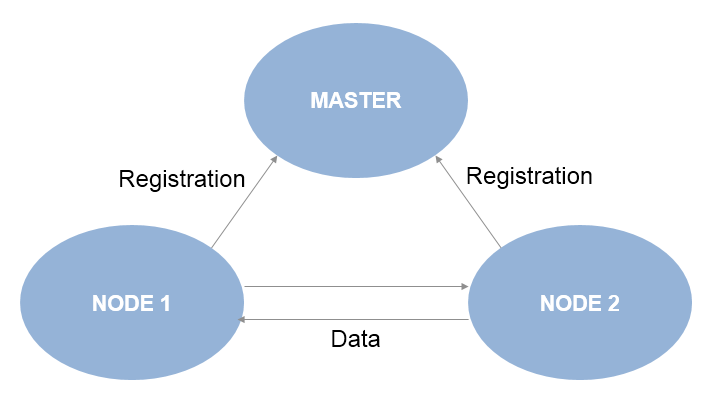

## Next Steps

- See [Exchange Data with ROS Publishers and Subscribers](docid:ros_ug.mw_fa34dc6f-351e-4ab5-8680-46563496814b) to explore publishers and subscribers in ROS.

*Copyright 2014-2015 The MathWorks, Inc.*